clear all
clc


dt = 0.005;
num_snaps = 1000;
num_traj = 200;
t_span = 0:dt:dt*num_snaps;
num_states = 1;


data_gen_type = 'controller'; % controller or random

% system 
params = containers.Map()


params = 

  Map with properties:

        Count: 0
      KeyType: char
    ValueType: any



a = 1.0;
b = 2.0;
c = 2.0;
d = 2.0;

% data for joint dynamics
if strcmp(data_gen_type,'random')
    for i = 1:num_traj
        i
        % Initialize the values
        X(i,1,1:num_states) = 0.1*(2*rand(num_states,1) - 1); %joint angles
        X(i,1,num_states+1:2*num_states) = 0.1*(2*rand(num_states,1) - 1); %joint velocity
        for j = 1:num_snaps
            tau(i,j,:) = 1*(2*rand(1,num_states) - 1); %input torques
    % 
            x_ddot = -a*X(i,j,1:num_states) - b*X(i,j,1:num_states)^3 - c*tau(i,j,:) - ...
                      d*X(i,j,num_states+1:2*num_states);
            X(i,j+1,num_states+1:2*num_states) = x_ddot*dt + X(i,j,num_states+1:2*num_states);
            X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);
    
             
        end
    end
elseif strcmp(data_gen_type,'controller')
    Kp = 16*eye(num_states);
    Kv = 8*eye(num_states);
    num_wp = 20;

    for i = 1:num_traj
        i

        % generate path
        t_end = dt*num_snaps; 
        for s = 1:num_wp
            if s == 1
                q_wp(:,1) = 0.1*(2*rand(num_states,1) - 1)';
                t_wp(:,1) = 0;
                q_wp_dot = 0.07*(2*rand(num_states,1) - 1);
            else
                t_wp(s) = s*t_end/num_wp;
                q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
                q_wp_dot = 0.07*(2*rand(num_states,1) - 1);
            end
        end

        [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));


        % Initialize the values
        X(i,1,1:num_states) = q_traj(:,1);%.*ul_joints + l_joints; %joint angles
        X(i,1,num_states+1:2*num_states) = qd_traj(:,1);%.*ul_joints; %joint velocity
        % X(i,1,2*num_states+1:3*num_states) = qddot_traj(:,1);
        for j = 1:num_snaps

            tau_dash(:,j) = qddot_traj(:,j) + Kv*(qd_traj(:,j) - reshape(X(i,j,num_states+1:2*num_states),[num_states,1])) + Kp*(q_traj(:,j) - reshape(X(i,j,1:num_states),[num_states,1]));
            tau(i,j,:) = -a*X(i,j,1:num_states) - b*X(i,j,1:num_states)^3 - c*tau_dash(:,j) - ...
                      d*X(i,j,num_states+1:2*num_states);


            x_ddot = -a*X(i,j,1:num_states) - b*X(i,j,1:num_states)^3 - c*tau(i,j,:) - ...
                      d*X(i,j,num_states+1:2*num_states);
            X(i,j+1,num_states+1:2*num_states) = x_ddot*dt + X(i,j,num_states+1:2*num_states);
            X(i,j+1,1:num_states) = X(i,j,num_states+1:2*num_states)*dt + X(i,j,1:num_states);

        end
    end

end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 146

i = 147

i = 148

i = 149

i = 150

i = 151

i = 152

i = 153

i = 154

i = 155

i = 156

i = 157

i = 158

i = 159

i = 160

i = 161

i = 162

i = 163

i = 164

i = 165

i = 166

i = 167

i = 168

i = 169

i = 170

i = 171

i = 172

i = 173

i = 174

i = 175

i = 176

i = 177

i = 178

i = 179

i = 180

i = 181

i = 182

i = 183

i = 184

i = 185

i = 186

i = 187

i = 188

i = 189

i = 190

i = 191

i = 192

i = 193

i = 194

i = 195

i = 196

i = 197

i = 198

i = 199

i = 200


figure()

for i = 1:num_traj
    plot(X(i,:,1),X(i,:,2), 'LineWidth',1)
    hold on
end

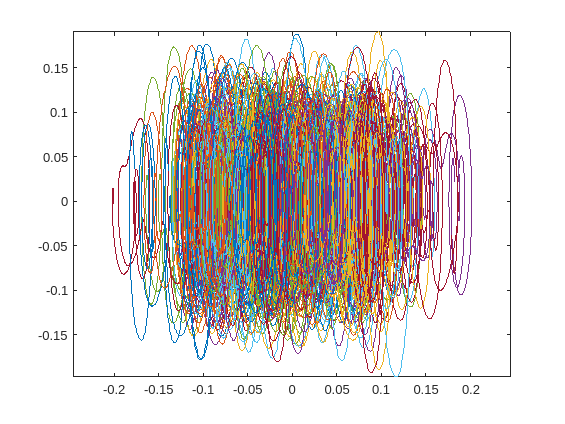


axis('equal')

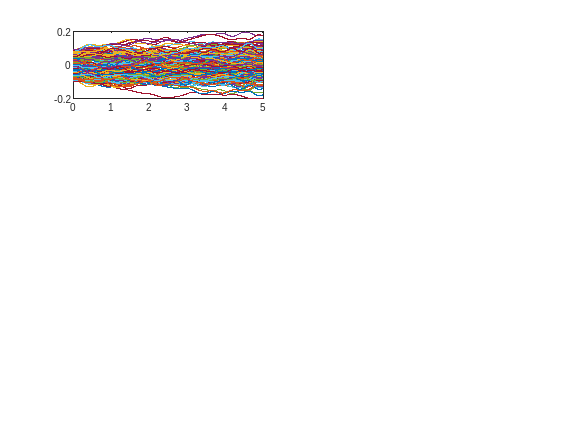

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i))
        hold on

    end
end

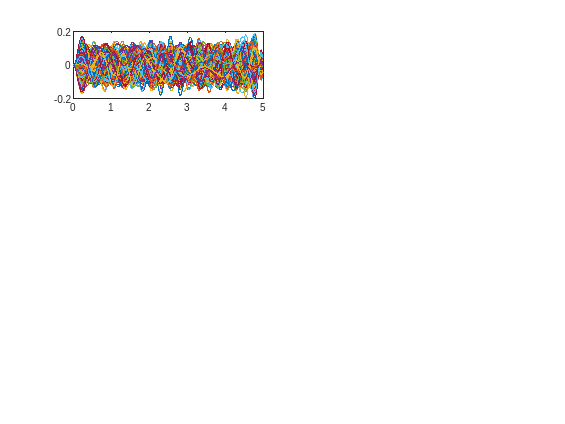

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X(j,:,i+num_states))
        hold on

    end
end

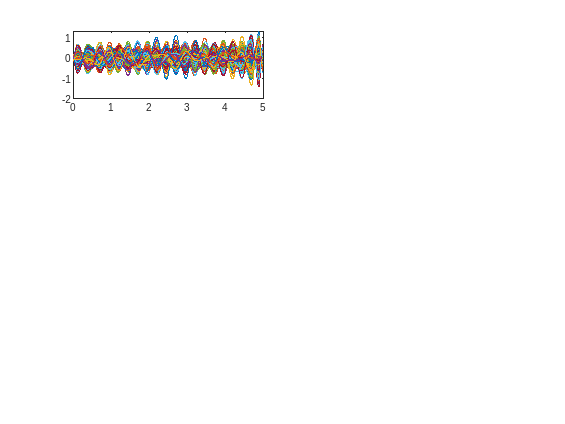

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('tau',num2str(i)))
    for j = 1:num_traj
        plot(t_span(1:end-1),tau(j,:,i))
        hold on

    end
end